clc;
clear all;
l1=30; %Length of Link 1
l2=30; %Length of Link 2
l3=10;  %Length of Link 3
l4 =10; %Length of Link 4

%   DH  = [  a_n  alpha_n  d_n  theta_n]
% DHparameter=[0 0 0.04 0;
%              0.12 pi/2 0 13*pi/30;
%              0.194 0 0 -23*pi/30;
%              0 -pi/2 0.176 0;
%              0 pi/2 0 pi/2;
%              0 pi/2 0 0]

% DHparameter=[0 0 4 0;
%              12 pi/2 0 0;
%              19.4 0 0 0;
%              0 -pi/2 17.6 0;
%              0 pi/2 0 0;
%              0 pi/2 0 0]
% DHparameter=[0 pi/2 0.04 0;
%              0.12 0 0 13*pi/30+pi/2;
%              0.194 -pi/2 0 -23*pi/30+pi/2;
%              0 0 0.176 0;
%              0 pi/2 0 pi/2;
%              0 0 0 0;
%              0.2 0 0 0;
%              -0.05 pi/2 0 pi/2];
% DHparameter = [0 0 0 0;
%                0 -pi/2 0.082 0;
%                0.082 0 0 -pi/2;
%                0 pi/2 0 pi/2;
%                0 -pi/2 0.1412 0;
%                0 pi/2 0 -pi/2;
%                0 0 0.120 0]

DHparameter = [0 0 0.082 0;
               0 pi/2 0 pi/2;
               0.1432 0 0 -pi/2;
               0 -pi/2 0.20 0;
               0 pi/2 0 pi/2;
               0 pi/2 0 0;
               0.2 0 0 0;
               0 0 0.05 0]

DHparameter =          0         0    0.0820         0
         0    1.5708         0    1.5708
    0.1432         0         0   -1.5708
         0   -1.5708    0.2000         0
         0    1.5708         0    1.5708
         0    1.5708         0         0
    0.2000         0         0         0
         0         0    0.0500         0


## `Defining the asymmetric robot as a rigid tree`

%Defining a Robot Rigid Body Tree 
dental = rigidBodyTree("MaxNumBodies",10,"DataFormat","column");

%Setting the Gravity matrix w.r.t to the base frame of robot.
dental.Gravity = [0 0 -9.81];

%Creating links and joints
body1 = rigidBody('Body1');
joint1 = rigidBodyJoint('Joint1','revolute');
% joint1.PositionLimits = [0 2*pi];
body1.Mass = 10;
body1.CenterOfMass = [0 0 0];

body2 = rigidBody('Body2');
joint2 = rigidBodyJoint('Joint2','revolute');

% joint2.HomePosition = 13*pi/30+pi/2;


body2.Mass = 10;
% body2.CenterOfMass = [0 0 0];


% joint2.PositionLimits = [-2*pi/3 0];
% 
body3 = rigidBody('Body3');
joint3 = rigidBodyJoint('Joint3','revolute');
body3.Mass = 10;

% joint3.HomePosition = -23*pi/30+pi/2;
% joint3.PositionLimits = [-10 10]; %Position limit defines the maximum extension/retraction from mean position for a prismatic joint. 

% body3.CenterOfMass = [0 0 0];

% joint3.PositionLimits = [-pi/3 pi/3];

body4 = rigidBody('Body4');
joint4 = rigidBodyJoint('Joint4','revolute');
body4.Mass = 10;


% joint4.PositionLimits = [0 2*pi];
                
body5 = rigidBody('Body5');
joint5 = rigidBodyJoint('Joint5','revolute');

% joint5.HomePosition = pi/2;
% joint5.PositionLimits = [-pi/4 pi/4];

% body5.Mass = 10;

body6 = rigidBody('Body6');
joint6 = rigidBodyJoint('Joint6','revolute');
% joint6.PositionLimits = [0 0.1];
% body6.Mass = 10;

% joint6.PositionLimits = [-pi/4 pi/4];

body7 =rigidBody('Body7');
joint7 = rigidBodyJoint('Joint7','fixed');

%Settings the transformations to each joint with DH parameter.
%Assigning the joint of each link with the object 

body8 =rigidBody('Body8');
joint8 = rigidBodyJoint('Joint8','fixed');


setFixedTransform(joint1,DHparameter(1,:),"mdh");
body1.Joint = joint1;
setFixedTransform(joint2,DHparameter(2,:),"mdh");
body2.Joint = joint2;
setFixedTransform(joint3,DHparameter(3,:),"mdh");
body3.Joint = joint3;
setFixedTransform(joint4,DHparameter(4,:),"mdh");
body4.Joint = joint4;
setFixedTransform(joint5,DHparameter(5,:),"mdh");
body5.Joint = joint5;
setFixedTransform(joint6,DHparameter(6,:),"mdh");
body6.Joint = joint6;

setFixedTransform(joint7,DHparameter(7,:),"mdh");
body7.Joint = joint7;

% setFixedTransform(joint8,DHparameter(8,:),"dh");
% body8.Joint = joint8;


addBody(dental,body1,'base');
addBody(dental,body2,'Body1');
addBody(dental,body3,'Body2');
addBody(dental,body4,'Body3');
addBody(dental,body5,'Body4');
addBody(dental,body6,'Body5');
addBody(dental,body7,'Body6');
% addBody(dental,body8,'Body7');


showdetails(dental)

--------------------
Robot: (7 bodies)

 Idx    Body Name    Joint Name    Joint Type    Parent Name(Idx)   Children Name(s)
 ---    ---------    ----------    ----------    ----------------   ----------------
   1        Body1        Joint1      revolute             base(0)   Body2(2)  
   2        Body2        Joint2      revolute            Body1(1)   Body3(3)  
   3        Body3        Joint3      revolute            Body2(2)   Body4(4)  
   4        Body4        Joint4      revolute            Body3(3)   Body5(5)  
   5        Body5        Joint5      revolute            Body4(4)   Body6(6)  
   6        Body6        Joint6      revolute            Body5(5)   Body7(7)  
   7        Body7        Joint7         fixed            Body6(6)   
--------------------


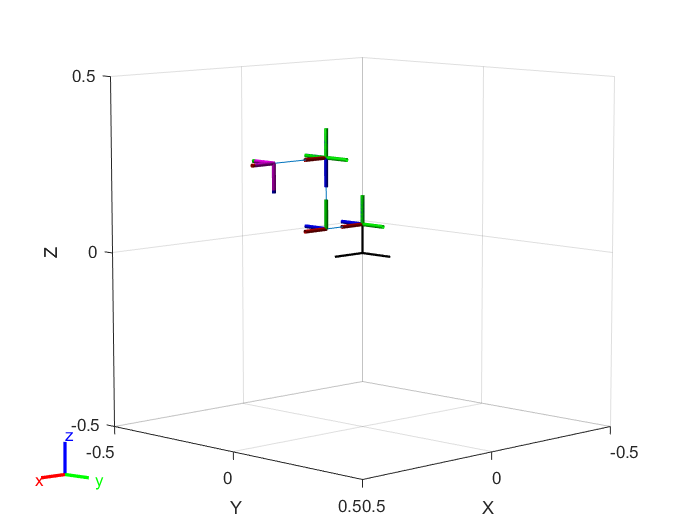

figure;
show(dental);

## `Denture, 3 - Teeth, 1 - Tooth, Final Tooth, Transformation and Shrink`

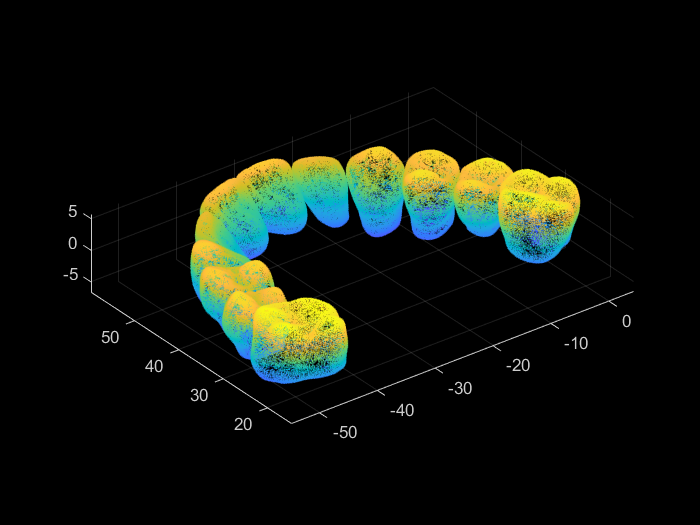

% Read and plot complete denture
stlData = stlread('stl/1-3dm.stl');
points = stlData.Points;
ptCloud = pointCloud(points);
figure
pcshow(ptCloud)

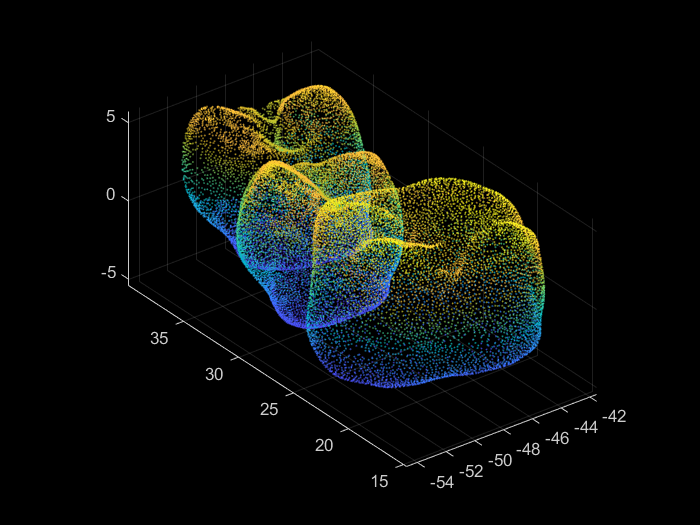


% Select and plot three teeth individually
roi = [-60 -40 10 40 -6 6]; % region of interest
indices = findPointsInROI(ptCloud,roi);
ptCloudB = select(ptCloud, indices);
pcshow(ptCloudB.Location);

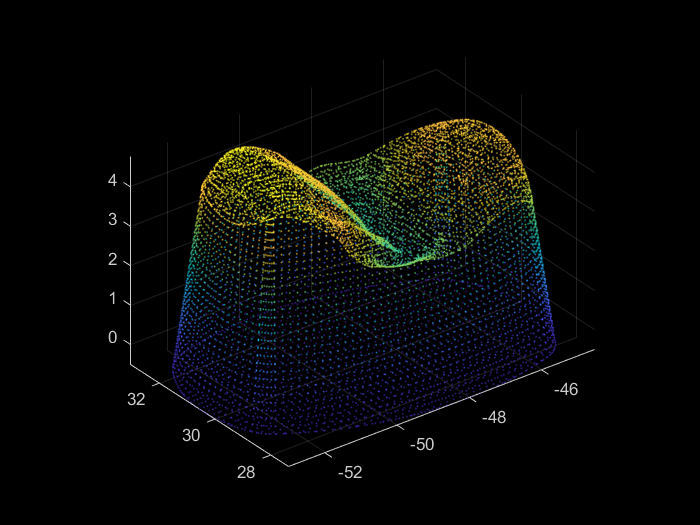


% Import and plot final model individually
stlData_fin = stlread("stl/1tooth_mesh2.STL");

points_fin= stlData_fin.Points;
ptCloud_fin = pointCloud(points_fin);
pcshow(ptCloud_fin);

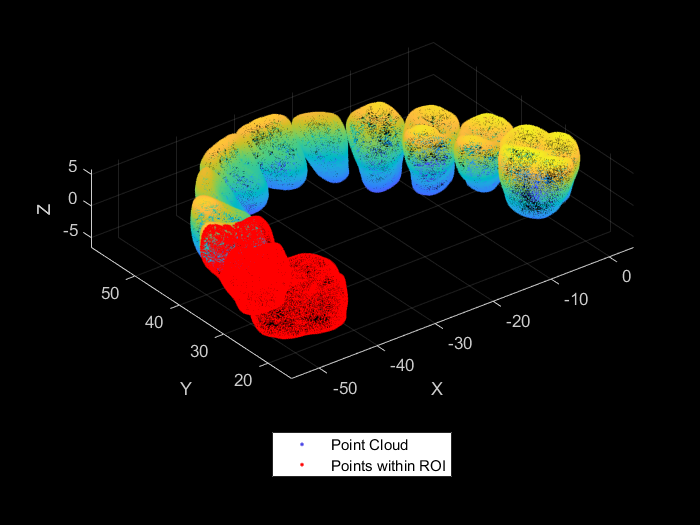


% Three teeth in the denture
figure
pcshow(ptCloud);
hold on;
pcshow(ptCloudB.Location,'r');
legend('Point Cloud','Points within ROI','Location','southoutside','Color',[1 1 1])
xlabel('X'); ylabel('Y'); zlabel('Z');
hold off;

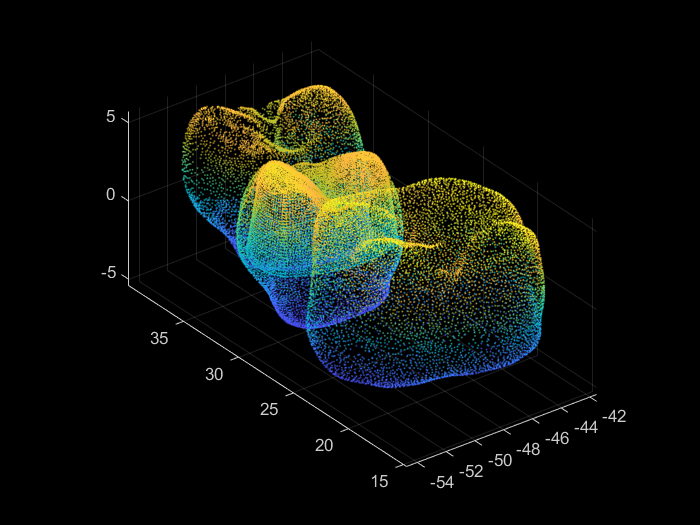


% Final tooth inside the considered tooth
figure
pcshow(ptCloudB.Location);
hold on;
pcshow(ptCloud_fin);
hold off;

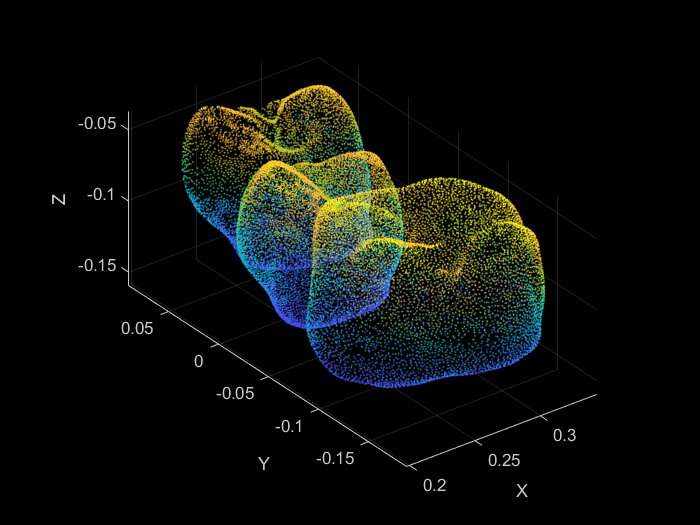


%Transformation (shrink and move)
Sx = 0.011;
Sy = 0.011;
Sz = 0.011;


tform = affine3d([Sx 0 0 0; 0 Sy 0 0; 0 0 Sz 0; 0 0 0 1]);
ptCloud_3t = pctransform(ptCloudB,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);
rot = [1 0 0; 0 1 0; 0 0 1];
zCoord = -0.1;
trans = [0.8 -0.35 zCoord];
tform = rigid3d(rot,trans);
ptCloud_3t = pctransform(ptCloud_3t,tform);
ptCloud_fin = pctransform(ptCloud_fin,tform);

figure
pcshow(ptCloud_3t)
xlabel('X'); ylabel('Y'); zlabel('Z')

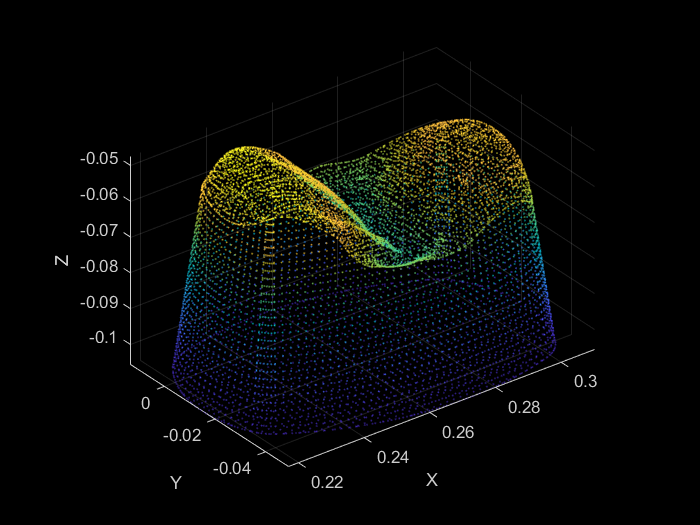

pcshow(ptCloud_fin)
xlabel('X'); ylabel('Y'); zlabel('Z')

## `Curves for end-effector path planning`

Algo

- set Z range

- get Z -> getContour

- get ordered points -> getOrderedPoints()

- smoothen curve -> smoothCurve()

- Make polyshape

- Expand polyshape

figure
allPoints = {};
r = 0.005

r = 0.0050

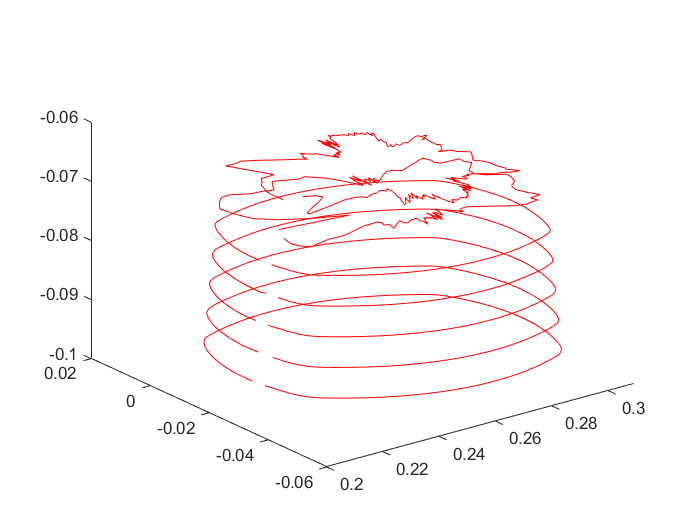

for i=1:7
    L = zCoord + (i-1)*r;
    H = zCoord + r + (i-1)*r;
    [a,b] = getContour(ptCloud_fin,L,H);
    P = getOrderedPoints(a,b);
    [smoothX,smoothY] = smoothCurve(P,35,2);
    
    points = downsample([smoothX',smoothY'],5);
   
    polyin = polyshape({points(:,1)},{points(:,2)});
    polyout = polybuffer(polyin,0.005);
    
    zin = (L+H)/2 * ones(length(polyin.Vertices),1);
    allPoints{i} = [points,zin];
%     zout = (L+H)/2 * ones(length(polyout.Vertices));
    
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),zin,"Color",[1 0 0]); hold on;
%     plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),zout,"Color",[0 1 0]);
end

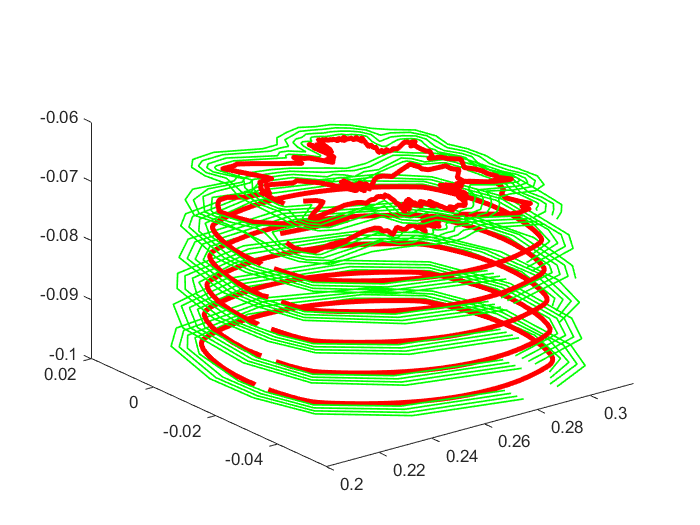

figure
for i=1:length(allPoints)
    polyin = polyshape({allPoints{1,i}(:,1)},{allPoints{1,i}(:,2)});
    plot3(polyin.Vertices(:,1),polyin.Vertices(:,2),allPoints{1,i}(:,3),...
            "Color",[1 0 0],"LineWidth",3);
    hold on;
    for j=1:4
        polyout = polybuffer(polyin,0.002*j);
        polyout.Vertices = downsample(polyout.Vertices,20);
        z = allPoints{1,i}(1,3)*ones(length(polyout.Vertices),1);
        allPoints{j+1,i} = [polyout.Vertices, z];
        plot3(polyout.Vertices(:,1),polyout.Vertices(:,2),z,...
                "Color",[0 1 0],"LineWidth",1);
    end
end

allPoints

allPoints = 5×7 cell array
    {86×3 double}    {57×3 double}    {86×3 double}    {62×3 double}    {82×3 double}    {161×3 double}    {328×3 double}
    {14×3 double}    {13×3 double}    {14×3 double}    {14×3 double}    {14×3 double}    { 67×3 double}    { 99×3 double}
    {14×3 double}    {13×3 double}    {14×3 double}    {14×3 double}    {14×3 double}    { 50×3 double}    { 66×3 double}
    {14×3 double}    {13×3 double}    {14×3 double}    {14×3 double}    {14×3 double}    { 41×3 double}    { 51×3 double}
    {14×3 double}    {13×3 double}    {14×3 double}    {13×3 double}    {14×3 double}    { 35×3 double}    { 42×3 double}


% Row = Top to Bottom - Inside to Outside
% Column = Left to Right - Bottom to Top

## `Save all quarters in arrays`

curve1 = allPoints{5,1}

curve1 =     0.2746   -0.0560   -0.0975
    0.2394   -0.0501   -0.0975
    0.2171   -0.0377   -0.0975
    0.2108   -0.0232   -0.0975
    0.2103   -0.0096   -0.0975
    0.2179    0.0094   -0.0975
    0.2286    0.0168   -0.0975
    0.2634    0.0200   -0.0975
    0.2954    0.0115   -0.0975
    0.3089    0.0025   -0.0975


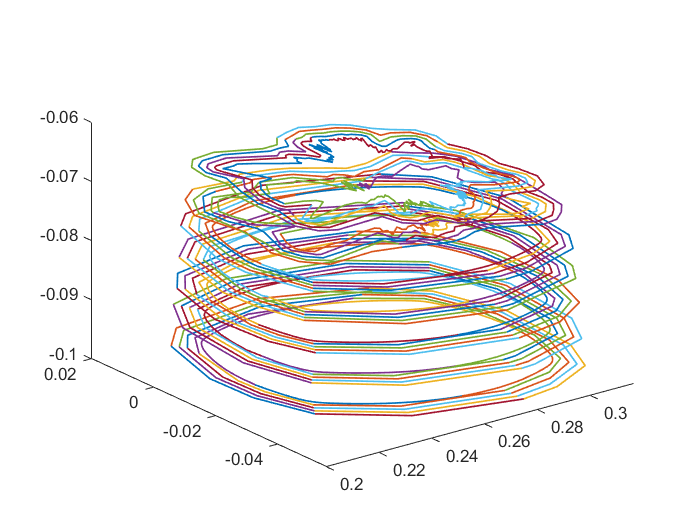

appendAllPoints = [];
figure

for i=1:7
    for j = 1:2 %Offsetting inner most contour fix
        [q1,q2,q3,q4] = getQuarters(allPoints{j,i},1);
        q1_arr{i,j} = q2;
        q2_arr{i,j} = q1;
        q3_arr{i,j} = q4;
        q4_arr{i,j} = q3;
        appendAllPoints = [appendAllPoints;q1;q2;q3;q4];
    end
    for j=2:5
        [q1,q2,q3,q4] = getQuarters(allPoints{j,i},1);
        q1_arr{i,j} = q1;
        q2_arr{i,j} = q2;
        q3_arr{i,j} = q3;
        q4_arr{i,j} = q4;
        appendAllPoints = [appendAllPoints;q1;q2;q3;q4];
    end
end

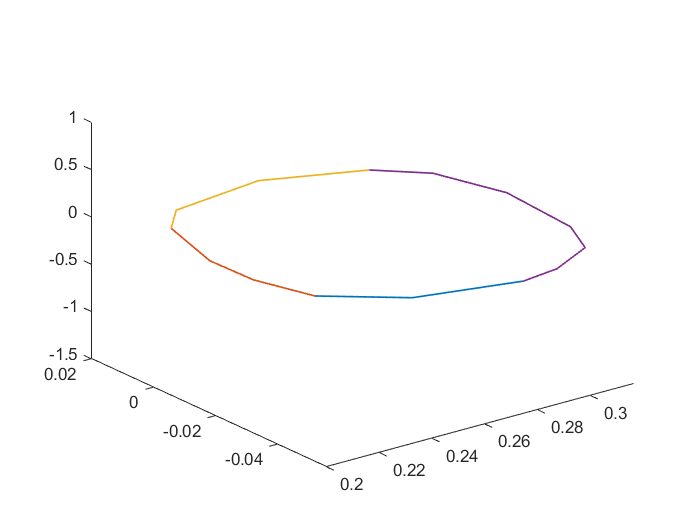

% Show a single curve.
figure
[q1,q2,q3,q4] = getQuarters(allPoints{5,1},1);


% q2 is front
% q1 is right
% q3 is left
% q4 is back

## `Splitting Geometry and Forming into Trajectory`

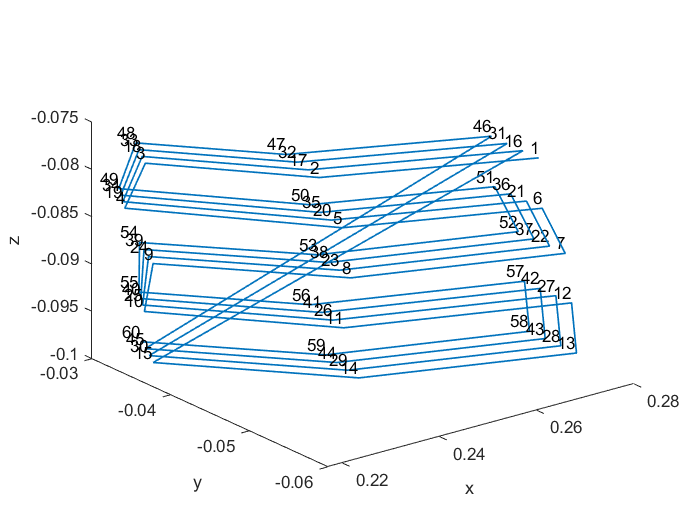

%Plot a single quarter
% figure
% for i=1:5
%     for j=1:5
%         plot3(q1_arr{i,j}(:,1),q1_arr{i,j}(:,2),q1_arr{i,j}(:,3),"LineWidth",1);hold on;
%     end
% end

q1_traj_arr = orderQuarter(q1_arr);
q2_traj_arr = orderQuarter(q2_arr);
q3_traj_arr = orderQuarter(q3_arr);
q4_traj_arr = orderQuarter(q4_arr);

q1_traj_arr_fixed = [];
for i = 1:60
    q1_traj_arr_fixed(i,:) = q1_traj_arr(i,:);
end

q2_traj_arr_fixed = [];
for i = 1:80
    q2_traj_arr_fixed(i,:) = q2_traj_arr(i,:);
end

q3_traj_arr_fixed = [];
for i = 1:80
    q3_traj_arr_fixed(i,:) = q3_traj_arr(i,:);
end

q4_traj_arr_fixed = [];
for i = 1:135
    q4_traj_arr_fixed(i,:) = q4_traj_arr(i,:);
end

save fixed_contour.mat q1_traj_arr_fixed q2_traj_arr_fixed q3_traj_arr_fixed q4_traj_arr_fixed

figure
plotQuarter(q1_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');

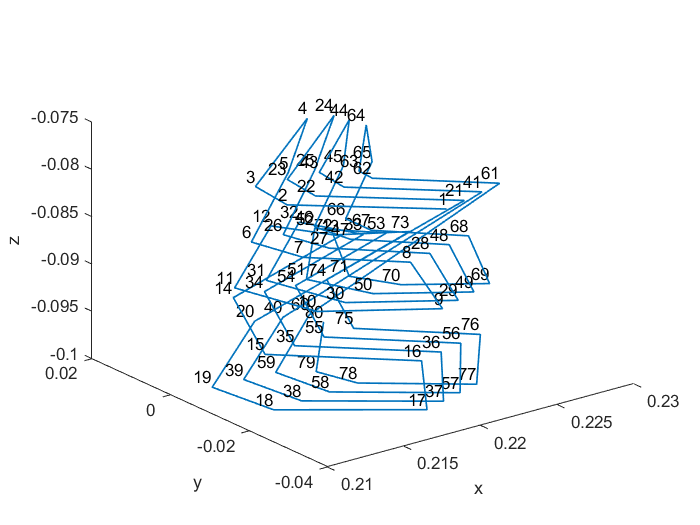

plotQuarter(q2_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');

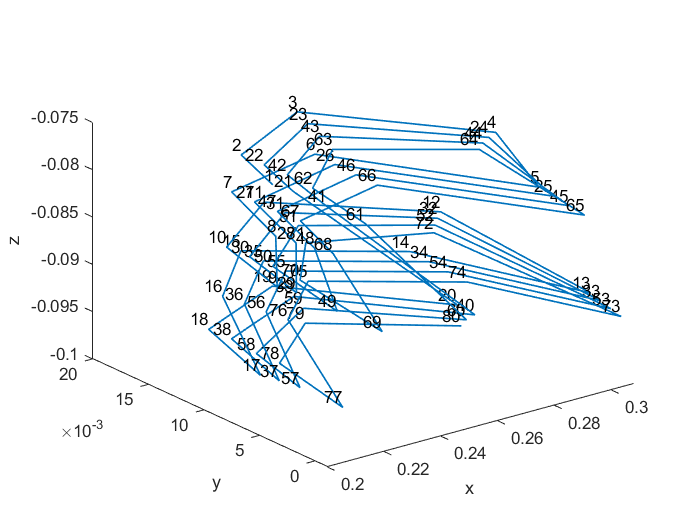

plotQuarter(q3_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');

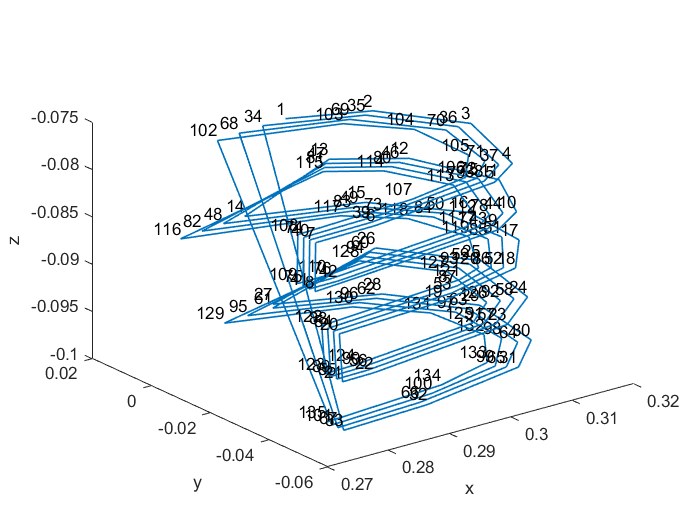

plotQuarter(q4_traj_arr_fixed);
xlabel('x'); ylabel('y'); zlabel('z');
hold off

MSH = collisionMesh(ptCloud_fin.Location)

MSH =   collisionMesh with properties:

    Vertices: [10770×3 double]
        Pose: [4×4 double]


worldCollisionArray = {MSH}

worldCollisionArray = 1×1 cell array
    {1×1 collisionMesh}


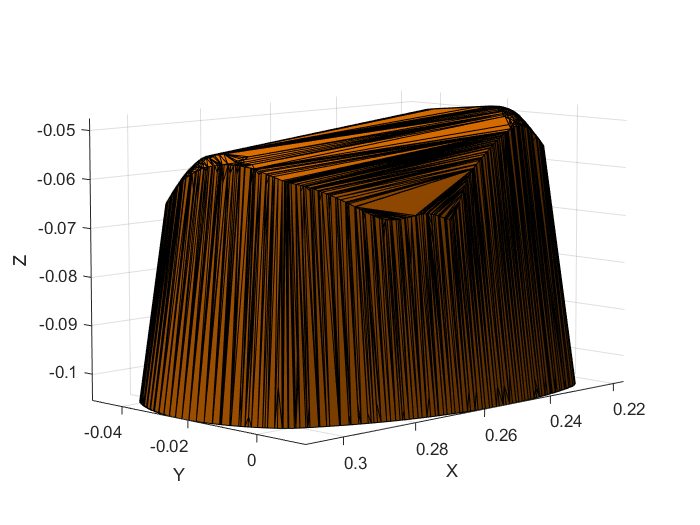

ax = exampleHelperVisualizeCollisionEnvironment(worldCollisionArray);

## `Calculate IK for Trajectories`

T = [0 0 -1 0; 0 -1 0 0;-1 0 0 0;0 0 0 1];
ik = inverseKinematics("RigidBodyTree",dental);
weights = [1 1 1 1 1 1];
q0 = homeConfiguration(dental);
qinitial = q0;
ik.SolverParameters.MaxIterations = 450000;
ik.SolverParameters.MaxTime = 1000;
for i = 1:length(q1_traj_arr_fixed)
%     point = q1_traj_arr(i,:);
%     pose = trvec2tform(q1_traj_arr_fixed(i,:)); %*axang2tform([1 1 1 0]);
    pose = trvec2tform(q1_traj_arr_fixed(i,:))*T;
    [qsol, solinfo] = ik("Body7",pose,weights,qinitial);
    q1_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9054e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1127e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1221e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 20
    NumRandomRestarts: 0
        PoseErrorNorm: 6.2684e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 26
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3760e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 7.0427e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0388e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7575e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 6.9241e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9994e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4312e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 2.3900e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0264e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 6.7893e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1091e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8524e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1647e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 9.9011e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 22
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6164e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 26
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4095e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 8.2509e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2826e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9053e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 7.6367e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 7.2968e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9790e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4248e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9255e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5307e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0560e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9799e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 2.0338e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 8.7102e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 5.3949e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 4.7298e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2008e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5496e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0645e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 8.1952e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 7.2636e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8082e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1704e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8654e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 9.5364e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 3.6117e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 7.4922e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0659e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 7.6052e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 5.0546e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7775e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 5.3056e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6750e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8810e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 8.6586e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 23
    NumRandomRestarts: 0
        PoseErrorNorm: 5.2965e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9843e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 4.4420e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7992e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 5.3567e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1370e-09
             ExitFlag: 1
               Status: 'success'


% pose = trvec2tform(q1_traj_arr_fixed(1,:))*T

q1_traj_arr_fixed(10,:)

ans =     0.2170   -0.0366   -0.0925


getTransform(dental,q1_config(:,10),'Body7')

ans =     0.0000    0.0000   -1.0000    0.2170
    0.0000   -1.0000   -0.0000   -0.0366
   -1.0000   -0.0000   -0.0000   -0.0925
         0         0         0    1.0000


weights = [0.4 0.4 0.4 1 1 1];
qinitial = q0;
for i = 1:length(q2_traj_arr_fixed)
%     pose = trvec2tform(q2_traj_arr_fixed(i,:))*axang2tform([1 1 1 pi]);
    pose = trvec2tform(q2_traj_arr_fixed(i,:))*T;
    [qsol, solinfo] = ik("Body7",pose,weights,qinitial);
    q2_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 6.3865e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 5.5408e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5503e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 6.6130e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 6.3055e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 4.6940e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 9.4431e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 4.2616e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 8.7241e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 4.1964e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2149e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0969e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 5.5556e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 5.7306e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7165e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 8.6255e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 26
    NumRandomRestarts: 0
        PoseErrorNorm: 5.5439e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1277e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 8.7232e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 8.4947e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 5.7733e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2933e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 5.7234e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0403e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 24
    NumRandomRestarts: 0
        PoseErrorNorm: 9.2979e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8991e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1893e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 9.6883e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1813e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8496e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5077e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 9.7043e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 5.5646e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7222e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 6.8137e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0338e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 26
    NumRandomRestarts: 0
        PoseErrorNorm: 1.8266e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 8.7203e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 7.5590e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 8.9750e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9127e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1790e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 8.5283e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 7.7599e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 26
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4036e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8999e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 8.7183e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 5.3064e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 6.4018e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8110e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 6.2200e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8773e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 7.2530e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9979e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2388e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 8.8946e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 26
    NumRandomRestarts: 0
        PoseErrorNorm: 4.7403e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9065e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0507e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2498e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 6.6043e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 4.4915e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 5.3713e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 8.6730e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 4.7496e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 7.5885e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 5.2306e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8582e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9675e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8309e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6428e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6979e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 9.6415e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7829e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 3.9007e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 6.3580e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 25
    NumRandomRestarts: 0
        PoseErrorNorm: 7.4566e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 6.2591e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 9.3193e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6170e-09
             ExitFlag: 1
               Status: 'success'


q2_config

q2_config =    -0.1610   -0.0892   -0.0452    0.0416    0.0390   -0.0570   -0.1046   -0.1563   -0.1676   -0.1219   -0.0473    0.0371    0.0650    0.0148   -0.0925   -0.1672   -0.1719   -0.1098   -0.0454    0.0433   -0.1541   -0.0865   -0.0474    0.0346    0.0320   -0.0586   -0.1002   -0.1497   -0.1601   -0.1186   -0.0487    0.0307    0.0572    0.0108   -0.0906   -0.1606   -0.1646   -0.1066   -0.0463    0.0370   -0.1472   -0.0838   -0.0495    0.0212    0.0261   -0.0588   -0.0944   -0.1431   -0.1528   -0.1154
   -0.8835   -0.9211   -0.9225   -0.8849   -0.9183   -0.9536   -0.9462   -0.9204   -0.9380   -0.9714   -0.9840   -0.9507   -0.9443   -0.9957   -1.0098   -0.9703   -0.9943   -1.0361   -1.0440   -1.0056   -0.8776   -0.9124   -0.9136   -0.8789   -0.9122   -0.9443   -0.9378   -0.9140   -0.9325   -0.9623   -0.9745   -0.9437   -0.9395   -0.9868   -1.0002   -0.9635   -0.9883   -1.0266   -1.0340   -0.9982   -0.8716   -0.9036   -0.9045   -0.8782   -0.9050   -0.9350   -0.9305   -0.9074   -0.9

getTransform(dental,q2_config(:,4),'Body7')

ans =     0.0000   -0.0000   -1.0000    0.2213
    0.0000   -1.0000    0.0000    0.0092
   -1.0000   -0.0000   -0.0000   -0.0775
         0         0         0    1.0000


ik.SolverParameters.MaxIterations = 45000;
ik.SolverParameters.MaxTime = 10;
weights = [0.3 0.3 0.3 1 1 1];
qinitial = q2_config(:,80);
for i = 1:length(q3_traj_arr_fixed)
%     pose = trvec2tform(q3_traj_arr_fixed(i,:))*axang2tform([1 1 1 pi]);
    pose = trvec2tform(q3_traj_arr_fixed(i,:))*T;
    [qsol, solinfo] = ik("Body7",pose,weights,qinitial);
    q3_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8027e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 9.2922e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1184e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 7.8445e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6731e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 4.1528e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2717e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 6.4292e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2028e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 4.5786e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0240e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8518e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 8.9474e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 30
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3888e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 6.8393e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 3.5985e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 7.0720e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 7.5476e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 7.2968e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8707e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3501e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2367e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3732e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 4.6532e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 7.6785e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 7.1805e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0335e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6952e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2549e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 4.1907e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 5.8358e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6871e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 8.4458e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 30
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0175e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3249e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 6.3294e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9349e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 6.5700e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 9.6370e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 30
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6147e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1871e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5723e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1742e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5335e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 30
    NumRandomRestarts: 0
        PoseErrorNorm: 6.7736e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9381e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1791e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2288e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 8.6612e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 5.6453e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3787e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 9.9262e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 7.6125e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 30
    NumRandomRestarts: 0
        PoseErrorNorm: 6.6626e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0681e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8397e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 5.2889e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 9.2531e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 5.3929e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 1.7338e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 9.5657e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 6.6809e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0138e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2108e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3152e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5558e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 6.5281e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5532e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 4.1973e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 6.2389e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5492e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 7.6556e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 6.4272e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 30
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3581e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 8.9311e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7106e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2035e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 8.1821e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 27
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0881e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 28
    NumRandomRestarts: 0
        PoseErrorNorm: 9.5922e-09
             ExitFlag: 1
               Status: 'success'


getTransform(dental,q3_config(:,60),'Body7')

ans =    -0.0000    0.0000   -1.0000    0.2903
    0.0000   -1.0000   -0.0000    0.0094
   -1.0000   -0.0000    0.0000   -0.0975
         0         0         0    1.0000


ik.SolverParameters.MaxIterations = 45000;
ik.SolverParameters.MaxTime = 100;
qinitial = q3_config(:,80);
weights=[0.1 0.1 0.1 1 1 1]

weights =     0.1000    0.1000    0.1000    1.0000    1.0000    1.0000


for i = 1:length(q4_traj_arr_fixed)
%     pose = trvec2tform(q4_traj_arr_fixed(i,:))*axang2tform([1 1 1 0]);
    pose = trvec2tform(q4_traj_arr_fixed(i,:))*T;
    [qsol, solinfo] = ik("Body7",pose,weights,qinitial);
    q4_config(:,i) = qsol;
    qinitial=qsol;
    solinfo
end

solinfo = struct with fields:
           Iterations: 34
    NumRandomRestarts: 0
        PoseErrorNorm: 6.5557e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8635e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 4.1199e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9384e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4198e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 7.8243e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 9.1313e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 9.1019e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 34
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0795e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 7.4767e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0292e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2327e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9571e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7607e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 3.2599e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 7.7979e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9213e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 6.0039e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4603e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9294e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3487e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 5.6806e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 34
    NumRandomRestarts: 0
        PoseErrorNorm: 8.1171e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0141e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1797e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4463e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 7.5056e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1746e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3427e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 5.9491e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 6.1474e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8868e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 3.5310e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 29
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0211e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 7.8864e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8098e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4363e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1047e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 6.9859e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 9.8969e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 9.3670e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4629e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 8.1252e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 3.5674e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 4.0340e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 3.4404e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 2.7873e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 2.1906e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 2.8831e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 4.1531e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 5.5120e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 5.6832e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8807e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 7.6882e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5397e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 5.7284e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 34
    NumRandomRestarts: 0
        PoseErrorNorm: 9.1659e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 5.1871e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 2.9673e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9691e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 7.7635e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4188e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 8.2927e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1603e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 6.0995e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3643e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8397e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 30
    NumRandomRestarts: 0
        PoseErrorNorm: 9.9051e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 9.0120e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 3.0696e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5149e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 8.0394e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 5.5376e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1471e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0191e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 4.6084e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 6.4770e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5569e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2882e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.2285e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 5.0797e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9257e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 3.7853e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 34
    NumRandomRestarts: 0
        PoseErrorNorm: 3.6233e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5679e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 4.5808e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 3.1937e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8820e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.5745e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 5.7794e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 8.3362e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0549e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 3.8673e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1701e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 6.0491e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 2.5568e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 6.6646e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2037e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 5.4299e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 8.2096e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 6.1902e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 30
    NumRandomRestarts: 0
        PoseErrorNorm: 2.6264e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 9.5838e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.9079e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 5.4981e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1037e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 1.3528e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 4.8273e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 9.6647e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 2.4253e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 5.1377e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 8.1082e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 8.2524e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.1513e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 4.1244e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3894e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 2.2663e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 4.5455e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.4292e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 4.3301e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 7.8896e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.0990e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6882e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 5.8372e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 34
    NumRandomRestarts: 0
        PoseErrorNorm: 4.4235e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 5.4999e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 7.4034e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 7.2740e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 4.9564e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6657e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 33
    NumRandomRestarts: 0
        PoseErrorNorm: 3.3249e-10
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 5.4948e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 31
    NumRandomRestarts: 0
        PoseErrorNorm: 1.6639e-08
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 6.1718e-09
             ExitFlag: 1
               Status: 'success'


solinfo = struct with fields:
           Iterations: 32
    NumRandomRestarts: 0
        PoseErrorNorm: 8.3844e-09
             ExitFlag: 1
               Status: 'success'


save q_configs q1_config q2_config q3_config q4_config;
% q_config = matfile('q_configs.mat');
% q1_config = q_config.q1_config;
% q1_config = trapveltraj(q1_config,length(q1_config(1,:)),"EndTime",2);


%Combine and add home config between
homeConfig = findHomeConfig(ptCloud_fin);
pose = trvec2tform(homeConfig);
home = ik("Body7",pose,weights,dental.homeConfiguration);
%Need to get traj between last config of each q and home, then add these
%trajs to q_tot
t = 20;
q_1tohome = trapveltraj([q1_config(:,length(q1_config(1,:))),home],t,"EndTime",2);
q_hometo2 = trapveltraj([home,q2_config(:,1)],t,"EndTime",2);
q_2tohome = trapveltraj([q2_config(:,length(q2_config(1,:))),home],t,"EndTime",2)

q_2tohome =     0.0124    0.0106    0.0053   -0.0036   -0.0161   -0.0322   -0.0518   -0.0742   -0.0968   -0.1194   -0.1420   -0.1645   -0.1871   -0.2095   -0.2291   -0.2452   -0.2577   -0.2666   -0.2719   -0.2737
   -0.9924   -1.0028   -1.0338   -1.0856   -1.1580   -1.2511   -1.3650   -1.4949   -1.6260   -1.7571   -1.8881   -2.0192   -2.1503   -2.2802   -2.3941   -2.4872   -2.5596   -2.6114   -2.6424   -2.6528
    0.1999    0.2037    0.2150    0.2338    0.2602    0.2941    0.3356    0.3829    0.4307    0.4784    0.5262    0.5739    0.6216    0.6690    0.7104    0.7444    0.7707    0.7896    0.8009    0.8047
   -0.0177   -0.0371   -0.0955   -0.1929   -0.3292   -0.5044   -0.7186   -0.9631   -1.2097   -1.4563   -1.7029   -1.9496   -2.1962   -2.4407   -2.6548   -2.8301   -2.9664   -3.0637   -3.1221   -3.1416
   -0.7783   -0.7654   -0.7267   -0.6621   -0.5717   -0.4555   -0.3135   -0.1514    0.0122    0.1758    0.3393    0.5029    0.6665    0.8286    0.9706    1.0869    1.1773    1.2418    

q_hometo3 = trapveltraj([home,q3_config(:,1)],t,"EndTime",2);
q_3tohome = trapveltraj([q3_config(:,length(q3_config(1,:))),home],t,"EndTime",2);
q_hometo4 = trapveltraj([home,q4_config(:,1)],t,"EndTime",2);


% q_tot = [q1_config ];
q_tot = [q1_config q2_config q3_config q4_config];

## `Finding the collision free trajectory`

% Need a mesh of the tooth
MSH = collisionMesh(ptCloud_fin.Location);
worldCollisionArray = {MSH};
robotCollision = isInCollision(q_tot, MSH, dental);
if ~robotCollision
    disp("The robot is in not in collision.")
else
    disp("The robot is in collision")
end

The robot is in not in collision.


## `Calculate and Plot Closest points`

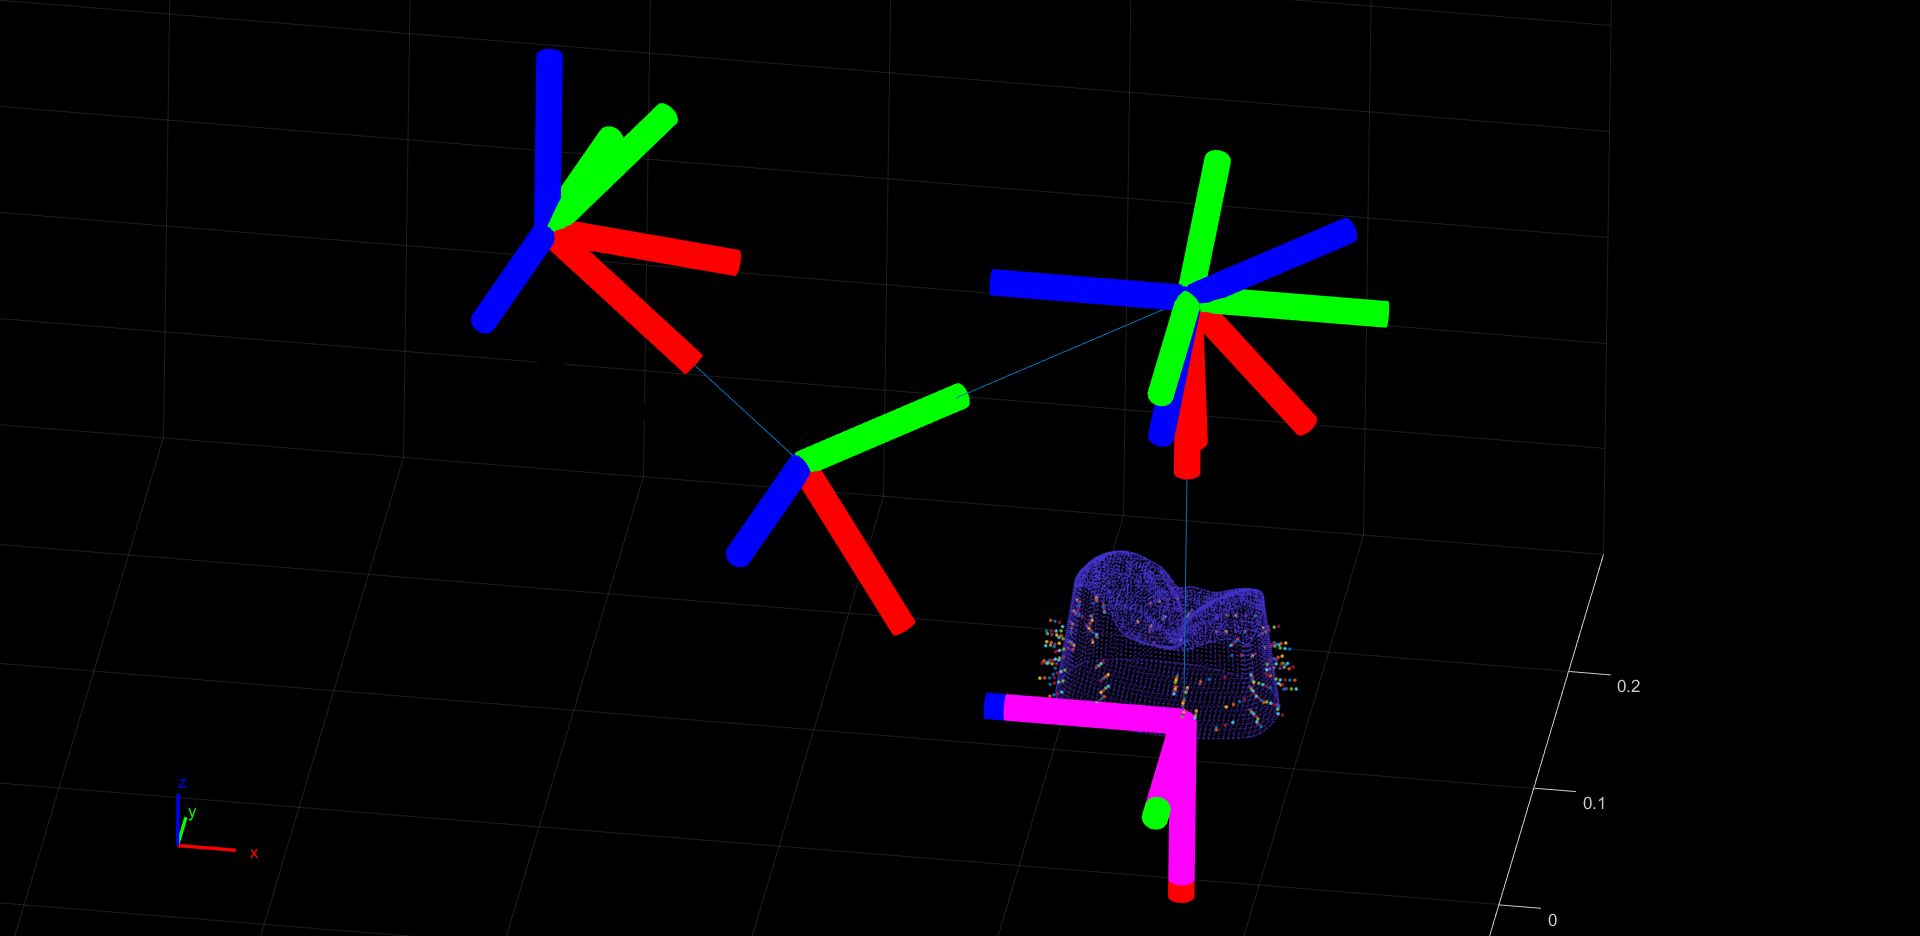

[minimum,ind,ee_arr] = min2pts(dental,q_tot,ptCloud_fin);

figure
pcshow(ptCloud_fin)
hold on
show(dental,home,'PreservePlot',false);
hold on
% plotQuarter(q1_traj_arr); hold on
% plotQuarter(q2_traj_arr); hold on
% plotQuarter(q3_traj_arr); hold on
% plotQuarter(q4_traj_arr); hold on
plotClosest(dental,q_tot,ee_arr,ind,ptCloud_fin);

% plotClosest(dental,q2_config,ee_arr,ind,ptCloud_fin);
% plotClosest(dental,q3_config,ee_arr,ind,ptCloud_fin);


## `Helper Functions`

### `getContour`

function [a,b] = getContour(ptCloud,L,H)
    k = 1;
    
    for i = 1:length(ptCloud.Location(:,3))
        j = ptCloud.Location(i,3);
        if j < H && j > L
            a(k,1) = ptCloud.Location(i,1);
            b(k,1) = ptCloud.Location(i,2);
            k = k+1;
        end
    end
end

### `getOrderedPoints`

function [P] = getOrderedPoints(a,b)
    P = [a'; b']; % coordinates / points 
    c = mean(P,2); % mean/ central point 
    d = P-c ; % vectors connecting the central point and the given points 
    th = atan2(d(2,:),d(1,:)); % angle above x axis
    [th, idx] = sort(th);   % sorting the angles 
    P = P(:,idx); % sorting the given points
    P = [P P(:,1)]; % add the first at the end to close the polygon 
end

### `smoothCurve`

function [smoothX, smoothY] = smoothCurve(P,windowWidth,polynomialOrder)
    smoothX = sgolayfilt(P(1,:), polynomialOrder, windowWidth);
    smoothY = sgolayfilt(P(2,:), polynomialOrder, windowWidth);
end

### `getQuarters`

function [q1,q2,q3,q4] = getQuarters(curve1,flag)    
    a = floor(length(curve1)/4);
%     curve1 = circshift(curve1,floor(a/2));
    curve1 = [curve1; curve1(1,:)];
    q1 = [curve1((1:a),1),curve1((1:a),2),curve1((1:a),3)];
    q2 = [curve1((a:2*a),1),curve1((a:2*a),2),curve1((a:2*a),3)];
    q3 = [curve1((2*a:3*a),1),curve1((2*a:3*a),2),curve1((2*a:3*a),3)];
    q4 = [curve1((3*a:end),1),curve1((3*a:end),2),curve1((3*a:end),3)];
    
    if(flag==1)
        plot3(q1(:,1),q1(:,2),q1(:,3),"LineWidth",1);hold on;
        plot3(q2(:,1),q2(:,2),q2(:,3),"LineWidth",1);hold on;
        plot3(q3(:,1),q3(:,2),q3(:,3),"LineWidth",1);hold on;
        plot3(q4(:,1),q4(:,2),q4(:,3),"LineWidth",1);hold on;
    end
end

function [ax, figHandle] = exampleHelperVisualizeCollisionEnvironment(collisionObjectArray)
%exampleHelperVisualizeCollisionEnvironment Visualize a set of collision objects
%   given a cell array of collision objects, create a figure that plots
%   these and with hold on. Return the handle to the figure's axis.
figHandle = figure;

% Show the first object
show(collisionObjectArray{1});

% Get axis properties and set hold
ax = gca;
hold all;

% Show remaining objects
for i = 2:numel(collisionObjectArray)
    show(collisionObjectArray{i}, "Parent", ax);
end

% Set axis properties
axis equal;

end

### `Closest Point Function:`

function [minimum,ind,ee_arr] = min2pts(bot,traj,ptCloud)
    hyp = zeros(length(ptCloud.Location(:,1)),length(traj(1,:)));
    ee_arr = zeros(length(traj(1,:)),3);
    
    for i = 1:1:length(traj(1,:))
        transform = getTransform(bot,traj(:,i),'Body7','base');
        ee = transform(1:3,4);
        ee_arr(i,:) = transpose(ee);
        d = abs(bsxfun(@minus, ee_arr(i,:), ptCloud.Location));
        hyp(:,i) = sqrt(d(:,1).^2 + d(:,2).^2 + d(:,3).^2); %Store hyp of each point at each frame
    end
    
    [minimum,ind] = min(hyp);
end

### `Plot Distance between ee and closest point function:`

function [] = plotClosest(bot,traj,ee_arr,ind,ptCloud)
    fps = 10;
    r = rateControl(fps);
    set(gcf,'Visible','on')
    pcshow(ptCloud)
    hold on
    axis([-0.3 0.4 -0.3 0.3 -0.2 0.2])
    for i = 1:1:length(traj(1,:))
        show(bot,traj(:,i),'PreservePlot',false);
        drawnow
        waitfor(r);
        hold on
%         line([ee_arr(i,1) ptCloud.Location(ind(i),1)],[ee_arr(i,2) ptCloud.Location(ind(i),2)],[ee_arr(i,3) ptCloud.Location(ind(i),3)],'Color','w')
        plot3(ee_arr(i,1),ee_arr(i,2),ee_arr(i,3),'Marker','.');
    end
    
end

### `Order Trajectory based on quarters:`

function [q_traj_arr] = orderQuarter(q_arr)
    %Construct q1 trajectory
    %Start from upper and outer contour
    len_q_z = length(q_arr(:,1)) - 2; %Exclude upper two bc top of tooth
    len_q_c = length(q_arr(1,:)); %Number of contours
    
    
    for j = 0:len_q_c-1 %Different contours
        for i = 0:len_q_z-1 %Different z levels
            q_traj = q_arr{len_q_z-i,len_q_c-j};
            if j == 0 && i == 0 %Need to initialize q1_traj_arr
                q_traj_arr = q_traj;
            else
                if mod(i,2) ~=0  %Reverse every other path
                    q_traj = flipud(q_traj);
                end
                q_traj_arr = vertcat(q_traj_arr,q_traj); %Append to bottom of array
            end
        end
    end
end

### `Plot Quarter Trajectory:`

function [] = plotQuarter(q_traj_arr)
    labels = cellstr( num2str([1:length(q_traj_arr(:,1))]') );
    
    plot3(q_traj_arr(:,1),q_traj_arr(:,2),q_traj_arr(:,3),"LineWidth",1);
    text(q_traj_arr(:,1),q_traj_arr(:,2),q_traj_arr(:,3), labels, 'VerticalAlignment','bottom', ...
                                 'HorizontalAlignment','right')
end

### `Finding Home Config`

function homeConfig = findHomeConfig(ptCloud_fin)
    x_max = max(ptCloud_fin.Location(:,1));
    x_min = min(ptCloud_fin.Location(:,1));
    y_max = max(ptCloud_fin.Location(:,2));
    y_min = min(ptCloud_fin.Location(:,2));
    x = (x_max + x_min)/2;
    y = (y_max + y_min)/2;
    z = -0.04;
    homeConfig = [x y z];
end

### `Check if path in collision or not`

function isTrajectoryInCollision = isInCollision(q, collisionMesh, robot)
    worldCollisionArray = {collisionMesh};
%     ik = inverseKinematics("RigidBodyTree",robot);
%     weights = ones(1,6);
%     
    rng(0); % start with a fixed seed to get repeatable results.
%     startConfig = ik("Body5",startPose,weights,robot.homeConfiguration);
%     endConfig = ik("Body5",endPose,weights,robot.homeConfiguration);
%     
%     
%     t = 200;
%     q = trapveltraj([homeConfiguration(robot),startConfig,endConfig],t,"EndTime",2);
    
    % Initialize outputs
    inCollision = false(length(q), 1); % Check whether each pose is in collision
    worldCollisionPairIdx = cell(length(q),1); % Provide the bodies that are in collision
    
    for i = 1:length(q)
        
        [inCollision(i),sepDist] = checkCollision(robot,q(:,i),worldCollisionArray,"IgnoreSelfCollision","on","Exhaustive","on");
        
        [bodyIdx,worldCollisionObjIdx] = find(isnan(sepDist)); % Find collision pairs
        worldCollidingPairs = [bodyIdx,worldCollisionObjIdx]; 
        worldCollisionPairIdx{i} = worldCollidingPairs;
        
    end
    
    %see if there is any collision
    isTrajectoryInCollision = any(inCollision);
end